# IIR elliptic BPF model

## Configure input parameters:

Sampling frequency [Hz] 

Fo =8096;
T = 1/Fo;

Bits per sample

NumOfBits = 16;

Filter passband

fp = [1250 ,2500];
Wp=fp/(Fo/2); % normalized passband

Filter stopband

fs = fp + [-250,250];
Ws=fs/(Fo/2); % normalized stopband

Filter ripples

max ripple in passband [dB]

Rp = 2.5;

min ripple in stopband [dB]

Rs =40;

Input test signal 

t = T*(0:1:Fo); % time axis [s] Num of Samples is Fo for 1 second
% Dirac impulse
x_in = zeros(size(t)); 
x_in(1) = 2^(NumOfBits-1); 
% scale the input signal to base 2 and save in memory (quantized)
scale_2 = 2^ceil(log2(max(abs(x_in))));
x_q = quantization(x_in/scale_2, NumOfBits, 1);

**Direct realization - MATLAB reference**

[n,Wn] = ellipord(Wp,Ws,Rp,Rs);
[b,a] = ellip(n,Rp,Rs,Wn);
N = 2*n; % for BPF
[H,meta_res] = freqz(b,a,Fo);
figure
subplot(2,1,1)
hold on
f = (meta_res/pi)*Fo/2;
Loss = -20*log10(abs(H));
rectangle('Position',[0, (Rs), fs(1)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fs(2)/1000, (Rs), (Fo/2-fs(2))/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fp(1)/1000, 0, (fp(2)-fp(1))/1000, Rp],'FaceColor',[.8 .8 .8],'Linestyle','none')
plot(f/1000, Loss)
title('Elliptic BPF - Direct realization - MATLAB ref')
xlabel('{\it f} [kHz]'), ylabel('Loss [dB]')
axis([-0.1,(Fo/2)/1000, -3,max(Loss)])

**Direct realization - DSP Simulation**

*s* – scaling coefficient

% scale the filter coeffs to base 2 and save in memory (quantized)
sc = 2^ceil(log2(max(abs([b a]))));
b_q = quantization(b/sc, NumOfBits,1);
a_q = quantization(a/sc, NumOfBits,1);


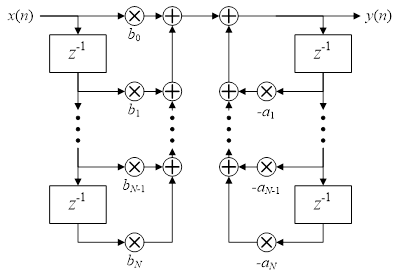 <<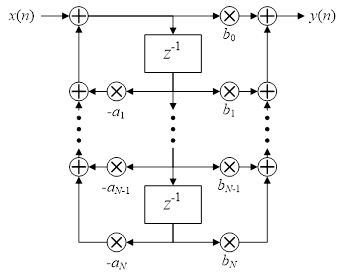

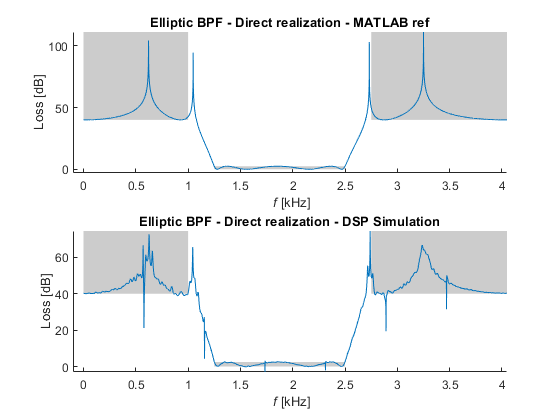

% filtering and save in memory (quantized)
sum_b = zeros(1,N);
x_z = zeros(1,N);
meta_res = zeros(1, length(x_q));
% b coeffs branch
for n = 1:length(x_q)
    sum_b(N) = quantization(b_q(N+1)*x_z(N), NumOfBits,1);
    % prev sums
    for k = N:-1:2
        sum_b(k-1) = quantization(sum_b(k)+ b_q(k)*x_z(k-1), NumOfBits,1);
    end
    meta_res(n) = quantization(sum_b(1)+ b_q(1)*x_q(n), NumOfBits,1);
    % shift delayed samples
    for z = N:-1:2
        x_z(z) = x_z(z-1);
    end
    % load next sample
    x_z(1) = x_q(n);
end
y_z = zeros(1,N);
sum_a = zeros(1,N);
y = zeros(1,length(x_q));
% a coeffs branch
for n = 1:length(x_q)
    sum_a(N) = quantization(-a_q(N+1)*y_z(N), NumOfBits,1);
    for k = N:-1:2
        sum_a(k-1)=  quantization(sum_a(k) - a_q(k)*y_z(k-1), NumOfBits,1);
    end
    y(n) = quantization((meta_res(n) + sum_a(1))*sc, NumOfBits,1);
    for z = N:-1:2
        y_z(z) = y_z(z-1);
    end
    y_z(1) = y(n);
end

%figure
subplot(2,1,2)
hold on
Y = fft(y);
M = abs(Y);
Loss = -20*log10(M);
Faxis = 0:Fo;
rectangle('Position',[0, (Rs), fs(1)/1000-0, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fs(2)/1000, (Rs), (Fo/2)/1000-fs(2)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fp(1)/1000, 0, fp(2)/1000-fp(1)/1000, Rp],'FaceColor',[.8 .8 .8],'Linestyle','none')
plot(Faxis(1:Fo/2)/1000, Loss(1:Fo/2))
xlabel('{\it f} [kHz]'), ylabel('Loss [dB]')
axis([-0.1,(Fo/2)/1000, -3,max(Loss)])
title('Elliptic BPF - Direct realization - DSP Simulation')

**Cascade realisation - MATLAB reference**

[sos,G] = tf2sos(b,a);
%Transfer Function to Second Order Section conversion
%SOS is an L by 6 matrix with the following structure:
% SOS = [ b01 b11 b21  1 a11 a21 
%         ...
%         b0L b1L b2L  1 a1L a2L ]
 
%Each row of the SOS matrix describes a 2nd order transfer function:
%                 b0k +  b1k z^-1 +  b2k  z^-2
%      Hk(z) =  -------------------------------
%                 1 +  a1k z^-1 +  a2k  z^-2 
%where k is the row index.
 
%G is a scalar which accounts for the overall gain of the system. If
%G is not specified, the gain is embedded in the first section. 
% The second order structure thus describes the system H(z) as:
%        H(z) = G*H1(z)*H2(z)*...*HL(z)

v = size(sos); NumOfSections = v(1);

Hcas = G;
for i=1:NumOfSections
      bi=sos(i, 1:3);
      ai=sos(i, 4:6);  
      [Hi,meta_res]=freqz(bi,ai,Fo);
      Hcas=Hcas.*Hi;
end

figure
subplot(2,1,1)
f = (meta_res/pi)*Fo/2;
Loss = -20*log10(abs(Hcas));
hold on
rectangle('Position',[0, (Rs), fs(1)/1000-0, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fs(2)/1000, (Rs), (Fo/2)/1000-fs(2)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fp(1)/1000, 0, fp(2)/1000-fp(1)/1000, Rp],'FaceColor',[.8 .8 .8],'Linestyle','none')
plot(f/1000, Loss)
title('Elliptic BPF - Cascade realization - MATLAB ref')
xlabel('{\it f} [kHz]'), ylabel('Loss [dB]')
axis([-0.1,(Fo/2)/1000, -3,max(Loss)])

**Cascade realization - DSP Simulation**

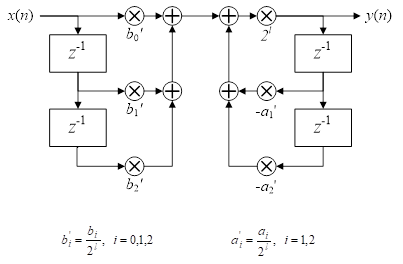

    

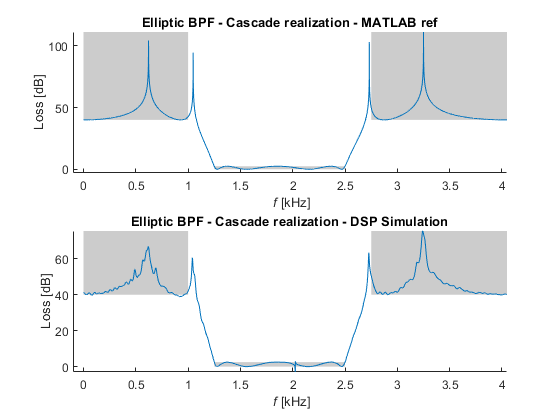

% scale the filter coeffs to base 2, for each section
skal_k_sek = zeros(1,3);
skal_k2_sek = zeros(1,3);
for i=1:NumOfSections
      b_sek=sos(i, 1:3);
      a_sek=sos(i, 4:6); 
      skal_k_sek(i)=max(abs([b_sek a_sek])); 
      skal_k2_sek(i)=ceil(log2(skal_k_sek(i)));
end
  
% filtering and save in memory (quantized)
Gk = quantization(G,NumOfBits,1);
ws=zeros(size(x_q)); ys=zeros(size(x_q)); xs=Gk*x_q;
for i=1:NumOfSections
    b_p0=sos(i, 1)/(2^skal_k2_sek(i));
    b_p0k=quantization(b_p0,NumOfBits,1);
    
    b_p1=sos(i, 2)/(2^skal_k2_sek(i));
    b_p1k=quantization(b_p1,NumOfBits,1);
    
    b_p2=sos(i, 3)/(2^skal_k2_sek(i));
    b_p2k=quantization(b_p2,NumOfBits,1);

    a_p1=sos(i, 5)/(2^skal_k2_sek(i));
    a_p1k=quantization(a_p1,NumOfBits,1);
    
    a_p2=sos(i, 6)/(2^skal_k2_sek(i));
    a_p2k=quantization(a_p2,NumOfBits,1);
    
    x2=0;x1=0;    
    for n=1:length(xs)
        z2=quantization(b_p2k*x2,NumOfBits,1);
        z1=quantization(z2+b_p1k*x1,NumOfBits,1);
        ws(n)=quantization(z1+b_p0k*xs(n),NumOfBits,1);
        x2=x1;
        x1=xs(n);
    end
    y2=0;y1=0;
    for n=1:length(xs)
        v2=quantization(-a_p2k*y2,NumOfBits,1);
        v1=quantization(v2-a_p1k*y1,NumOfBits,1);
        ys(n)=quantization(ws(n)+v1,NumOfBits,1)*2^skal_k2_sek(i);
        y2=y1;
        y1=ys(n);
    end
    xs=ys;
end
y_kas=xs;

%figure
subplot(2,1,2)
hold on
Ykas=fft(y_kas);
Mkas=abs(Ykas);
Loss = -20*log10(Mkas);
Faxis = 0:Fo;
rectangle('Position',[0, (Rs), fs(1)/1000-0, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fs(2)/1000, (Rs), (Fo/2)/1000-fs(2)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fp(1)/1000, 0, fp(2)/1000-fp(1)/1000, Rp],'FaceColor',[.8 .8 .8],'Linestyle','none')
plot(Faxis(1:Fo/2)/1000, Loss(1:Fo/2))
xlabel('{\it f} [kHz]'), ylabel('Loss [dB]')
axis([-0.1,(Fo/2)/1000, -3,max(Loss)])
title('Elliptic BPF - Cascade realization - DSP Simulation')